mu_E = 4e5

mu_E = 400000

mu_S = 1.3e11

mu_S = 1.3000e+11

mu_J = 1.3e8

mu_J = 130000000

R_E = 6400

R_E = 6400

R_S = 7e5

R_S = 700000

R_J = 7e4

R_J = 70000

aE = 1.5e8

aE = 150000000

AU = aE;

rJ = 5.2*AU;
vJ = 13.0;
gamma_J = deg2rad(5)

gamma_J = 0.0873

theta_aJ = deg2rad(90)

theta_aJ = 1.5708


eJ = sqrt((rJ*vJ^2/mu_S-1)^2*cos(gamma_J)^2+sin(gamma_J)^2)

eJ = 0.0883

aJ = -mu_S/(2*(vJ^2/2-mu_S/rJ))

aJ = 7.9108e+08

aC = 8*AU

aC = 1.2000e+09

eC = 0.8

eC = 0.8000


rph = 25*R_J

rph = 1750000

rC = rJ

rC = 780000000

pC = aC*(1-eC^2)

pC = 4.3200e+08


theta_ao_C = acos(pC/(rC*eC)-1/eC)

theta_ao_C = 2.1624

rad2deg(theta_ao_C)

ans = 123.8964


vC_o = sqrt(2*mu_S/rC-mu_S/aC)

vC_o = 15

gamma_oC = acos(sqrt(mu_S*pC)/(rC*vC_o))

gamma_oC = 0.8756

rad2deg(gamma_oC)

ans = 50.1699

v_inf_J = sqrt(vC_o^2+vJ^2-2*vC_o*vJ*cos(abs(gamma_J)+abs(gamma_oC)))

v_inf_J = 13.0864

ah = mu_J/v_inf_J^2

ah = 7.5911e+05

ah/R_J

ans = 10.8444


eh = rph/ah+1

eh = 3.3053

bh = ah*sqrt(eh^2-1)

bh = 2.3915e+06

bh/R_J

ans = 34.1646


delta = 2*asin(1/eh)

delta = 0.6147

rad2deg(delta)

ans = 35.2206


phi = (pi-delta)/2

phi = 1.2634

rad2deg(phi)

ans = 72.3897


rho = asin(vJ/v_inf_J*sin(abs(gamma_J)+abs(gamma_oC)))

rho = 0.9535

rad2deg(rho)

ans = 54.6300


dv_eq = sqrt(2*v_inf_J^2*(1-cos(delta)))

dv_eq = 7.9183

alpha = pi-phi-rho

alpha = 0.9247

rad2deg(alpha)

ans = 52.9803

dv_eq*[sin(alpha) 0 cos(alpha)]

ans =     6.3222         0    4.7675



vC_n = sqrt(vC_o^2+dv_eq^2-2*vC_o*dv_eq*cos(rho+phi))

vC_n = 20.7540

theta = asin(dv_eq/vC_n*sin(rho+phi))

theta = 0.3095

gamma_nC = gamma_oC-theta

gamma_nC = 0.5661

rad2deg(gamma_nC)

ans = 32.4342

a = 5*R_E

a = 32000

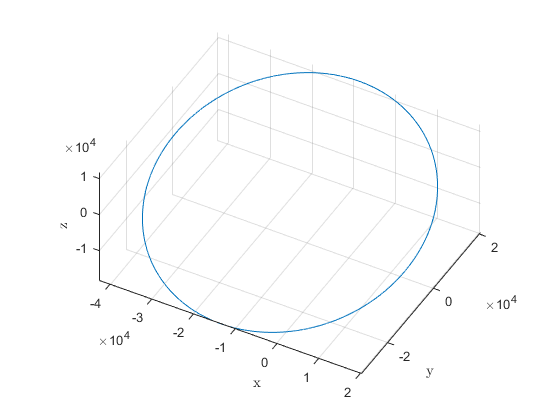

e = 0.4;
RAAN = 0;
AOP = deg2rad(30);
i = deg2rad(30);

figure
plot_orbit_3d(e,a,RAAN,AOP,i);

% view([1 0 0])

p = a*(1-e^2)

p = 26880

theta_ao = deg2rad(60)

theta_ao = 1.0472

r = p/(1+e*cos(theta_ao))

r = 2.2400e+04

v = sqrt(2*mu_E/r-mu_E/a)

v = 4.8181

gamma_o = acos(sqrt(mu_E*p)/(r*v))

gamma_o = 0.2810

rad2deg(gamma_o)

ans = 16.1021


rot = C313(0,pi/2,i)

rot =     0.0000   -1.0000         0
    0.8660    0.0000   -0.5000
    0.5000    0.0000    0.8660


rot'*[0 -0.5 0]'

ans =    -0.4330
   -0.0000
    0.2500


c = 5*R_E

c = 32000

r1 = 3*R_E

r1 = 19200

r2 = 4*R_E

r2 = 25600

am = 1/4*(r1+r2+c)

am = 19200

epsilon = -mu_E/(2*am)

epsilon = -10.4167

function C = C313(omega,theta,i)
    C = [cos(omega)*cos(theta)-sin(omega)*cos(i)*sin(theta) -cos(omega)*sin(theta)-sin(omega)*cos(i)*cos(theta) sin(omega)*sin(i);
        sin(omega)*cos(theta)+cos(omega)*cos(i)*sin(theta) -sin(omega)*sin(theta)+cos(omega)*cos(i)*cos(theta) -cos(omega)*sin(i);
        sin(i)*sin(theta) sin(i)*cos(theta) cos(i)];
end